Requisitos: tener un interprete de python y chebfun en la pestaña de add-ons. 

Ejecutar pyversion("C:\Users\Luis\anaconda3\python.exe") con el folder de python, solo una vez al iniciar matlab. Descargar mpmath para python e importarlo en matlab

Cálculo de los zeros no triviales de la función zeta de riemman

function zeros_t = zerost(n)
    % 
    %   Función que calcula los pares de zeros no triviales de 
    %   la función zeta de riemman
    %
    %   Inputs
    %       n: cantidad de pares de ceros a calcular
    %       
    %   Output
    %       zeros_t: lista con los ceros

    mpmath = py.importlib.import_module('mpmath');
    mpmath.mp.dps = 15; % decimales de precisión
    zeros_t = arrayfun(@(k) mpmath.zetazero(int32(k)), 1:n, UniformOutput=0);
    zeros_t = cellfun(@(z) double(py.float(z.imag).real), zeros_t, UniformOutput=0)';

    % realizando los pares
    zeros_t = cell2mat(zeros_t);
    zeros_t = 0.5+1i*zeros_t;
    zeros_t = [zeros_t; 1-zeros_t];
end

Función mobius

function m = mobius(n)
    % 
    %   Función Möbius en un punto n, que es una condición de ser 
    %   un entero positivo libre de cuadrados, o sea, que en su 
    %   factorización no tiene un factor repetido.
    %
    %   Inputs
    %       n: cantidad de pares de ceros a calcular
    %       
    %   Output
    %       m: condición de ser entero positivo libre de cuadrados, con
    %            1: si n tiene una cantidad par de divisores primos
    %           -1: si n tiene una cantidad impar de divisores primos
    %            0: si n no es un entero positivo libre de cuadrados

    if n == 1
        m = 1;
        return;
    end
    factors = factor(n);
    unique_factors = unique(factors);
    if numel(factors) ~= numel(unique_factors)
        m = 0;
        return;
    end
    % si no tiene factores repetidos, entonces unos
    m = (-1)^numel(unique_factors);
end

Función integral logarítmica

function li = li_function(y)
    % 
    %   Aproximación numérica de la integral logarítmica 
    %
    %   Inputs
    %       y: valor a evaluar
    %       
    %   Output
    %       li: valor de la integral

    if imag(y) == 0
        li = integral(@(t) 1 ./ log(t), 2, y, 'ArrayValued', true);
    else
        li = integral(@(t) 1 ./ log(t), 0, y, 'ArrayValued', true);
    end
end

Aproximación base

function R = R_function(x, N)
    % 
    %   Cálculo de la función R, aproximación de "grado" 0 a Pi 
    %
    %   Inputs
    %       x: Punto en el cual evaluar R(x)
    %       N: Límite superior de la suma
    %       
    %   Output
    %       R: valor R(x)

    % Inicializar la suma
    R = 0;

    for n = 1:N
        % Calcular la función de Möbius para n
        mu_n = mobius(n);

        % Calcular li
        li_term = li_function(x^(1/n));

        % Sumar el término correspondiente
        R = R + (mu_n / n) * li_term;
    end
end

Creando la escalera de primos

val = 200; 
prueba = primes(val);
escalera = sort([prueba, prueba, val]);
contadores = sort([1:numel(prueba), 0:(numel(prueba))]);

Dibujando la primera aproximación

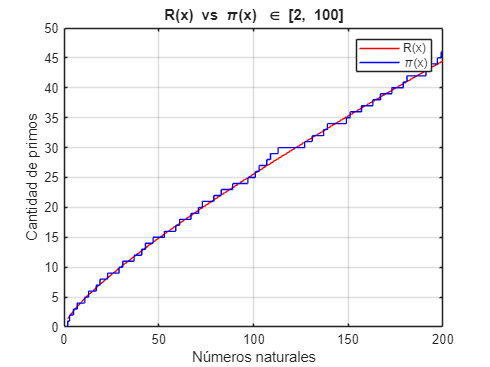

figure(1);
plot(2:val, arrayfun(@(x) R_function(x, 100), 2:val), 'r')
hold on;
plot(escalera, contadores, 'b')
xlabel('Números naturales');
ylabel('Cantidad de primos');
title('R(x) vs \pi(x) \in [2, 200]' );
grid on;
hold off;
legend('R(x)', '\pi(x)')

Cálculo de Rk, con k el número de ceros de la función zeta de riemman utilizados

function [xx, yy] = Rk(n, val)
    % 
    %   Cálculo de la función Rk, aproximación de "grado" k a Pi 
    %
    %   Inputs
    %       val: Punto máximo a evaluar Rk(x)
    %       n: cantidad de zeros de riemman a usar
    %       
    %   Output
    %       xx: valores del linspace
    %       yy: valores de Rk(x)


    % calcula los ceros no triviales de la función zeta de riemman
    zeros_t = zerost(n);

    % base de los cálculos de integrales con chebyshev
    x  = chebfun('x',[2 val]);
    f1 = 1./log(x)- 1./((x.^2-1).*x.*log(x));
    f2 = @(z) exp(z)./z;
    intF1 = chebfun(sum(f1,2,x),[2 val]);
    
    % cota a numeros primos
    mbk = nan(ceil(log(val)/log(2)-1),1); 

    % precalcula mobius
    for k = 1:size(mbk,1)
        mbk(k) = mobius(k)/k;
    end
    
    nz = 3*(val-3)+1;
    xx  = linspace(3,val,nz);
    yy = nan(nz,1);

    % realiza el cálculo de la integral logarítmica compleja
    for j = 1:size(xx,2)
        xhat = xx(j);
        N = ceil(log(xhat)/log(2)-1);
        b = 0;
        for k = 1:N
            if(mbk(k)~=0)
                v = log(xhat)/k*imag(zeros_t);
                integrand = @(s) f2(s+1i*v);
                res_int = integral(integrand,-inf,log(xhat)/k/2, 'ArrayValued',true);
                J  = intF1(xhat^(1./k))-real(sum(res_int))+.4919628194400546;
                b  = b + J*mbk(k);
            end
        end
        yy(j) = b;
    end
end

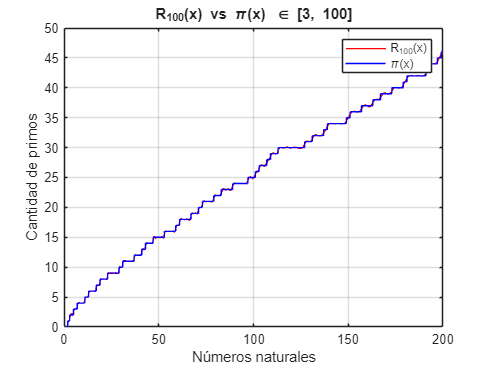

n = 100;
[xx, yy] = Rk(n, val);
figure(2)
plot(xx, yy, 'linewidth', 1, 'color', 'r');
hold on;
plot(escalera, contadores, 'b');
xlabel('Números naturales');
ylabel('Cantidad de primos');
title(strcat('R_{', num2str(n), '}(x)',' vs \pi(x) \in [3, 200]') );
legend(strcat('R_{', num2str(n), '}(x)'), '\pi(x)'); 
grid on;
hold off;